cd /home/mic-ciciolla/Documents/università/underactuated-robs/MICHE/hopping-robot-2D/
clear 
pause(0.1)
close all
pause(0.1)

# One-Legged Hopping Robot

#### Parameters [m] and [kg]

M1=1; % Leg mass [kg]
M2=10; % Body mass [kg]

I1=1; % Leg moment of Inertia [kg-m^2]
I2=10; %Body moment of Inertia [kg-m^2]

r1=0.5; % [m]
r2=0.4; % [m]

k0=1; % [m]
KL=10^4; % [Nt/m]

KL2=10^5; % [Nt/m]
BL2=125; % [Nt-s/m]

KG=10^3; % [Nt/m]
BG=75; % [Nt-s/m]

H = 0.4;%[m]

g=9.81;

#### Initial Conditions

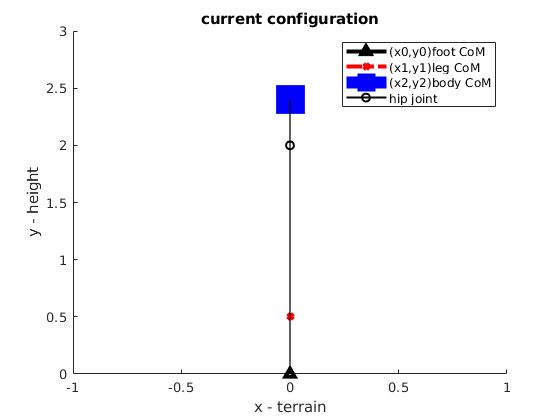

ini_theta1=0;
ini_theta1_d=0;

ini_theta2=0;
ini_theta2_d=0;

% ini_w=k0;
ini_w=2;
ini_w_d=0;

ini_x0=0;
ini_x0_d=0;

ini_y0 =0; % [m]
ini_y0_d=0;

ini_x1=ini_x0+r1*sin(ini_theta1);
ini_x1_d=0;

ini_y1=ini_y0+r1*cos(ini_theta1);
ini_y1_d=0;

ini_x2=ini_x1+r2*sin(ini_theta2);
ini_x2_d=0;

ini_y2=ini_y0+ini_w+r2*cos(ini_theta2);
ini_y2_d=0;

% plotting initial setup
foot(1,1) = ini_x0; foot(1,2) = ini_y0;
leg(1,1) = ini_x1; leg(1,2) = ini_y1;
body(1,1) = ini_x2; body(1,2) = ini_y2;

drawRobot(foot,leg,body,ini_theta1,ini_w);

#### Theta1_desired for torque control (equation 1)

theta1_des=0;

**Desired system energy to jump to height H (equation 14)**

desired_energy = M1*g*(H+r1) + M2*g*(H+k0+r2);

**Maximum compression of leg during stance**

deltaw = (M2*g)/KL + sqrt( ((M2^2*g^2)/KL^2) + 2*g*H*(M1+M2)^2/(M2*KL) );

**SIMULINK**


simtime = 20; %simulation time
SimDec=sim('HoppingRobotModel2',simtime); % Execution of the simulation in Simulink

fprintf("--------------------  Process completed ----------------------- ")